#### Part 3

slowmotion = load("slowmotion.mat");

IQ = slowmotion.iq;
s = slowmotion.s;
sm_framerate = s.Framerate_fps;
sm_depthIncrease_iq = s.iq.DepthIncrementIQ_m;
sm_startDepth_iq = s.iq.StartDepthIQ_m;
sm_num_beams_iq = s.iq.BeamsIQ;
sm_samples_iq = s.iq.SamplesIQ;
sm_frames_iq = s.iq.FramesIQ;
tissue = slowmotion.tissue;
sm_gain_iq = s.iq.feflowgain_dB;
sm_dyn_iq = s.iq.DynRange_dB;
sm_frsig = s.iq.frsIQ_Hz;


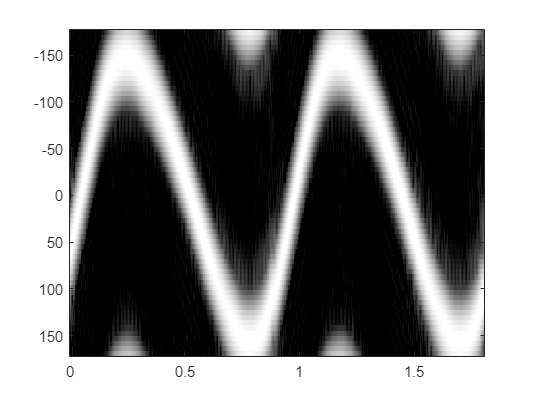

middle_beam = squeeze(IQ(:,4,:));
timeaxis=[1:s.iq.FramesIQ]/s.Framerate_fps;
depthaxis=[1:s.iq.SamplesIQ]*s.iq.DepthIncrementIQ_m*100;
%since y axis is the samples and x axis is the frames
y_axis = sm_startDepth_iq:sm_depthIncrease_iq:(sm_samples_iq-1)*sm_depthIncrease_iq + sm_startDepth_iq;
x_axis = 0:1/sm_framerate:(sm_frames_iq-1)*1/sm_framerate;
Nfft = 64;
crop = 16;
dyn = 40;
gain = -90;
depthindex = round(size(IQ,1)/2)-10:round(size(IQ,1)/2)+10;
P = zeros(Nfft, sm_frames_iq-crop+1);
for n=1:sm_frames_iq-crop+1
    iqsegm = middle_beam(depthindex,n+[0:crop-1])';
    iqsegm = iqsegm.*(hamming(crop)*ones(1,length(depthindex)));
    P(:,n) = mean(abs(fftshift(fft(iqsegm,Nfft))).^2,2);
end
freqAxis = (([0:Nfft-1]/Nfft)-0.5)*sm_framerate;
figure(), imagesc(x_axis,freqAxis,10*log10(P));
colormap(gray(255));
caxis([-dyn 0]-gain)


#### Part 4

fastmotion = load("fastmotion.mat");

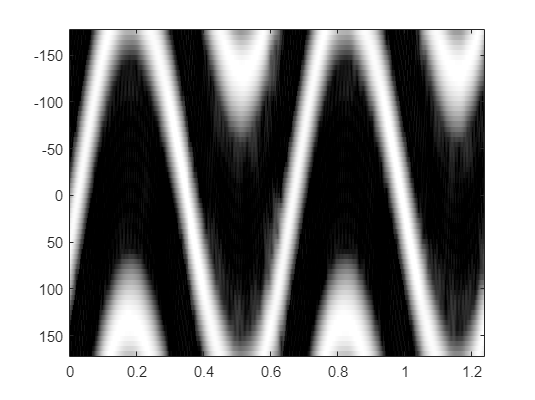

IQ_fm = fastmotion.iq;
f = fastmotion.s;
fm_framerate = f.Framerate_fps;
fm_depthIncrease_iq = f.iq.DepthIncrementIQ_m;
fm_startDepth_iq = f.iq.StartDepthIQ_m;
fm_num_beams_iq = f.iq.BeamsIQ;
fm_samples_iq = f.iq.SamplesIQ;
fm_frames_iq = f.iq.FramesIQ;
fm_tissue = fastmotion.tissue;
fm_gain_iq = f.iq.feflowgain_dB;
fm_dyn_iq = f.iq.DynRange_dB;
fm_frsig = f.iq.frsIQ_Hz;

middle_beam_fm = squeeze(IQ_fm(:,4,:));
%since y axis is the samples and x axis is the frames
y_axis_fm = fm_startDepth_iq:fm_depthIncrease_iq:(fm_samples_iq-1)*fm_depthIncrease_iq + fm_startDepth_iq;
x_axis_fm = 0:1/fm_framerate:(fm_frames_iq-1)*1/fm_framerate;
timeaxis=[1:fm_frames_iq]/fm_framerate;
Nfft_fm = 64;
crop_fm = 16;
dyn_fm = 40;
gain_fm = -90;
depthindex_fm = round(size(IQ_fm,1)/2)-10:round(size(IQ_fm,1)/2)+10;
P_fm = zeros(Nfft_fm, fm_frames_iq-crop_fm+1);
for n_fm=1:fm_frames_iq-crop+1
    iqsegm_fm = middle_beam_fm(depthindex_fm,n_fm+[0:crop_fm-1])';
    iqsegm_fm = iqsegm_fm.*(hamming(crop_fm)*ones(1,length(depthindex_fm)));
    P_fm(:,n_fm) = mean(abs(fftshift(fft(iqsegm_fm,Nfft_fm))).^2,2);
end
freqAxis_fm = (([0:Nfft_fm-1]/Nfft_fm)-0.5)*fm_framerate;
figure(), imagesc(x_axis_fm,freqAxis_fm,10*log10(P_fm));
colormap(gray(255));
caxis([-dyn_fm 0]-gain_fm)

P_fm_extend = [P_fm;P_fm;P_fm];

v_nyq_p = (f.Framerate_fps)/(2);
v_nyq_n = (-f.Framerate_fps)/(2);

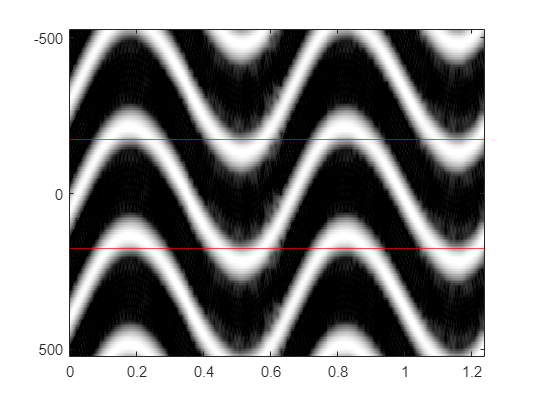


frequencyaxis=([0:Nfft_fm-1]/Nfft_fm)-0.5;
frequencyaxis=[frequencyaxis-1, frequencyaxis, frequencyaxis+1]*fm_framerate;
figure(), imagesc(x_axis_fm,frequencyaxis,10*log10(P_fm_extend));
hold on
yline(v_nyq_p,'r');
yline(v_nyq_n,'r');
colormap(gray(255));
caxis([-dyn_fm 0]-gain_fm);

#### Part 5

slowmotion_clutter = load("slowmotion_clutter.mat");

IQ_c = slowmotion_clutter.iq;
s_c = slowmotion_clutter.s;
smc_framerate = s_c.Framerate_fps;
smc_depthIncrease_iq = s_c.iq.DepthIncrementIQ_m;
smc_startDepth_iq = s_c.iq.StartDepthIQ_m;
smc_num_beams_iq = s_c.iq.BeamsIQ;
smc_samples_iq = s_c.iq.SamplesIQ;
smc_frames_iq = s_c.iq.FramesIQ;
tissue_c = slowmotion_clutter.tissue;
smc_gain_iq = s_c.iq.feflowgain_dB;
smc_dyn_iq = s_c.iq.DynRange_dB;
smc_frsig = s_c.iq.frsIQ_Hz;


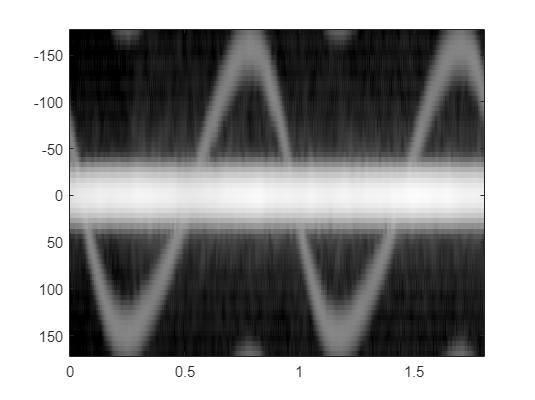

middle_beam_c = squeeze(IQ_c(:,4,:));
timeaxis=[1:s_c.iq.FramesIQ]/s_c.Framerate_fps;
depthaxis=[1:s_c.iq.SamplesIQ]*s_c.iq.DepthIncrementIQ_m*100;
%since y axis is the samples and x axis is the frames
y_axis_c = smc_startDepth_iq:smc_depthIncrease_iq:(smc_samples_iq-1)*smc_depthIncrease_iq + smc_startDepth_iq;
x_axis_c = 0:1/smc_framerate:(smc_frames_iq-1)*1/smc_framerate;
Nfft_c = 64;
crop_c = 16;
dyn_c = 40;
gain_c = -90;
depthindex_c = round(size(IQ_c,1)/2)-10:round(size(IQ_c,1)/2)+10;
P_c = zeros(Nfft_c, smc_frames_iq-crop_c+1);
for n_c=1:smc_frames_iq-crop_c+1
    iqsegm_c = middle_beam_c(depthindex_c,n_c+[0:crop_c-1])';
    iqsegm_c = iqsegm_c.*(hamming(crop_c)*ones(1,length(depthindex_c)));
    P_c(:,n_c) = mean(abs(fftshift(fft(iqsegm_c,Nfft_c))).^2,2);
end
freqAxis_c = (([0:Nfft_c-1]/Nfft_c)-0.5)*smc_framerate;
figure(), imagesc(x_axis_c,freqAxis_c,10*log10(P_c));
colormap(gray(255));
caxis([-dyn_c 0]-gain_c)

Basic filter

N = 2;
%b=ones(1,N); %=boxcar(N). May also use hamming(N), hanning(N), ....
b = hamming(N);
b=b/sum(b); %Normalization of filter coefficients
iq_lp=filter(b,1,middle_beam_c,[],2)

iq_lp = 	1.0e+03 *

  -1.6820 - 0.3150i  -3.3570 - 0.5415i  -3.3775 - 0.4725i  -3.3420 - 0.4870i  -3.3090 - 0.5995i  -3.2915 - 0.8250i  -3.1460 - 0.9015i  -2.8770 - 0.7475i  -2.7395 - 0.6320i  -2.7670 - 0.6810i  -2.7490 - 0.7160i  -2.7310 - 0.7635i  -2.6215 - 0.8330i  -2.5335 - 0.8760i  -2.6085 - 0.8755i  -2.7035 - 0.7600i  -2.6150 - 0.7310i  -2.5830 - 0.6785i  -2.7045 - 0.5720i  -2.7160 - 0.4640i  -2.7175 - 0.5280i  -2.7485 - 0.5525i  -2.8060 - 0.4485i  -2.9045 - 0.5020i  -3.0085 - 0.6390i  -3.0450 - 0.9075i  -3.0665 - 0.9665i  -3.1470 - 0.9625i  -3.1200 - 1.1685i  -3.1110 - 1.3745i  -3.2335 - 1.4295i  -3.2585 - 1.2355i  -3.1920 - 0.9805i  -3.1345 - 0.8175i  -3.1630 - 0.7195i  -3.3080 - 0.5860i  -3.3540 - 0.4400i  -3.3520 - 0.2970i  -3.3525 - 0.3035i  -3.3470 - 0.4035i  -3.3745 - 0.4505i  -3.2655 - 0.3715i  -3.1025 - 0.3695i  -3.1445 - 0.4755i  -3.1810 - 0.5010i  -3.1600 - 0.5670i  -3.1055 - 0.4845i  -2.9840 - 0.3270i  -3.0145 - 0.3360i  -2.9960 - 0.4380i
  -0.0040 - 0.0195i   0.0265 

filtered_middle_beam_c = middle_beam_c-iq_lp

filtered_middle_beam_c = 	1.0e+03 *

  -1.6820 - 0.3150i   0.0070 + 0.0885i  -0.0275 - 0.0195i   0.0630 + 0.0050i  -0.0300 - 0.1175i   0.0475 - 0.1080i   0.0980 + 0.0315i   0.1710 + 0.1225i  -0.0335 - 0.0070i   0.0060 - 0.0420i   0.0120 + 0.0070i   0.0060 - 0.0545i   0.1035 - 0.0150i  -0.0155 - 0.0280i  -0.0595 + 0.0285i  -0.0355 + 0.0870i   0.1240 - 0.0580i  -0.0920 + 0.1105i  -0.0295 - 0.0040i   0.0180 + 0.1120i  -0.0195 - 0.1760i  -0.0115 + 0.1515i  -0.0460 - 0.0475i  -0.0525 - 0.0060i  -0.0515 - 0.1310i   0.0150 - 0.1375i  -0.0365 + 0.0785i  -0.0440 - 0.0745i   0.0710 - 0.1315i  -0.0620 - 0.0745i  -0.0605 + 0.0195i   0.0355 + 0.1745i   0.0310 + 0.0805i   0.0265 + 0.0825i  -0.0550 + 0.0155i  -0.0900 + 0.1180i   0.0440 + 0.0280i  -0.0420 + 0.1150i   0.0415 - 0.1215i  -0.0360 + 0.0215i   0.0085 - 0.0685i   0.1005 + 0.1475i   0.0625 - 0.1455i  -0.1045 + 0.0395i   0.0680 - 0.0650i  -0.0470 - 0.0010i   0.1015 + 0.0835i   0.0200 + 0.0740i  -0.0505 - 0.0830i   0.0690 - 0.0190i
  -0.0040 - 

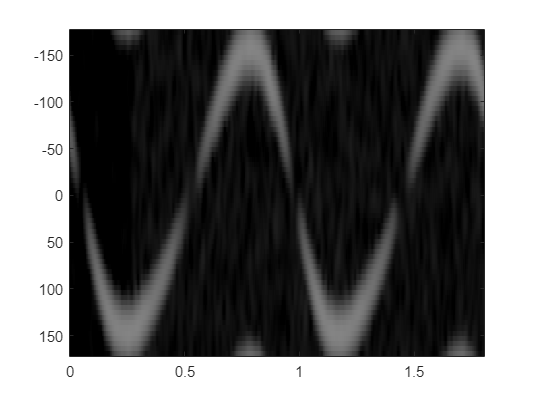

P_c_f = zeros(Nfft_c, smc_frames_iq-crop_c+1);
for n_c=1:smc_frames_iq-crop_c+1
    iqsegm_c = filtered_middle_beam_c(depthindex_c,n_c+[0:crop_c-1])';
    iqsegm_c = iqsegm_c.*(hamming(crop_c)*ones(1,length(depthindex_c)));
    P_c_f(:,n_c) = mean(abs(fftshift(fft(iqsegm_c,Nfft_c))).^2,2);
end

freqAxis_c = (([0:Nfft_c-1]/Nfft_c)-0.5)*smc_framerate;
figure(), imagesc(x_axis_c,freqAxis_c,10*log10(abs(P_c_f)));
colormap(gray(255));
caxis([-dyn_c 0]-gain_c)

N = 2;
b=ones(1,N); %=boxcar(N). May also use hamming(N), hanning(N), ....
%b = hamming(N);
b=b/sum(b); %Normalization of filter coefficients
iq_lp=filter(b,1,middle_beam_c,[],2)

iq_lp = 	1.0e+03 *

  -1.6820 - 0.3150i  -3.3570 - 0.5415i  -3.3775 - 0.4725i  -3.3420 - 0.4870i  -3.3090 - 0.5995i  -3.2915 - 0.8250i  -3.1460 - 0.9015i  -2.8770 - 0.7475i  -2.7395 - 0.6320i  -2.7670 - 0.6810i  -2.7490 - 0.7160i  -2.7310 - 0.7635i  -2.6215 - 0.8330i  -2.5335 - 0.8760i  -2.6085 - 0.8755i  -2.7035 - 0.7600i  -2.6150 - 0.7310i  -2.5830 - 0.6785i  -2.7045 - 0.5720i  -2.7160 - 0.4640i  -2.7175 - 0.5280i  -2.7485 - 0.5525i  -2.8060 - 0.4485i  -2.9045 - 0.5020i  -3.0085 - 0.6390i  -3.0450 - 0.9075i  -3.0665 - 0.9665i  -3.1470 - 0.9625i  -3.1200 - 1.1685i  -3.1110 - 1.3745i  -3.2335 - 1.4295i  -3.2585 - 1.2355i  -3.1920 - 0.9805i  -3.1345 - 0.8175i  -3.1630 - 0.7195i  -3.3080 - 0.5860i  -3.3540 - 0.4400i  -3.3520 - 0.2970i  -3.3525 - 0.3035i  -3.3470 - 0.4035i  -3.3745 - 0.4505i  -3.2655 - 0.3715i  -3.1025 - 0.3695i  -3.1445 - 0.4755i  -3.1810 - 0.5010i  -3.1600 - 0.5670i  -3.1055 - 0.4845i  -2.9840 - 0.3270i  -3.0145 - 0.3360i  -2.9960 - 0.4380i
  -0.0040 - 0.0195i   0.0265 

filtered_middle_beam_c = middle_beam_c-iq_lp

filtered_middle_beam_c = 	1.0e+03 *

  -1.6820 - 0.3150i   0.0070 + 0.0885i  -0.0275 - 0.0195i   0.0630 + 0.0050i  -0.0300 - 0.1175i   0.0475 - 0.1080i   0.0980 + 0.0315i   0.1710 + 0.1225i  -0.0335 - 0.0070i   0.0060 - 0.0420i   0.0120 + 0.0070i   0.0060 - 0.0545i   0.1035 - 0.0150i  -0.0155 - 0.0280i  -0.0595 + 0.0285i  -0.0355 + 0.0870i   0.1240 - 0.0580i  -0.0920 + 0.1105i  -0.0295 - 0.0040i   0.0180 + 0.1120i  -0.0195 - 0.1760i  -0.0115 + 0.1515i  -0.0460 - 0.0475i  -0.0525 - 0.0060i  -0.0515 - 0.1310i   0.0150 - 0.1375i  -0.0365 + 0.0785i  -0.0440 - 0.0745i   0.0710 - 0.1315i  -0.0620 - 0.0745i  -0.0605 + 0.0195i   0.0355 + 0.1745i   0.0310 + 0.0805i   0.0265 + 0.0825i  -0.0550 + 0.0155i  -0.0900 + 0.1180i   0.0440 + 0.0280i  -0.0420 + 0.1150i   0.0415 - 0.1215i  -0.0360 + 0.0215i   0.0085 - 0.0685i   0.1005 + 0.1475i   0.0625 - 0.1455i  -0.1045 + 0.0395i   0.0680 - 0.0650i  -0.0470 - 0.0010i   0.1015 + 0.0835i   0.0200 + 0.0740i  -0.0505 - 0.0830i   0.0690 - 0.0190i
  -0.0040 - 

P_c_f = zeros(Nfft_c, smc_frames_iq-crop_c+1);
for n_c=1:smc_frames_iq-crop_c+1
    iqsegm_c = filtered_middle_beam_c(depthindex_c,n_c+[0:crop_c-1])';
    iqsegm_c = iqsegm_c.*(hamming(crop_c)*ones(1,length(depthindex_c)));
    P_c_f(:,n_c) = mean(abs(fftshift(fft(iqsegm_c,Nfft_c))).^2,2);
end

freqAxis_c = (([0:Nfft_c-1]/Nfft_c)-0.5)*smc_framerate;
figure(), imagesc(x_axis_c,freqAxis_c,10*log10(abs(P_c_f)));
colormap(gray(255));
caxis([-dyn_c 0]-gain_c)

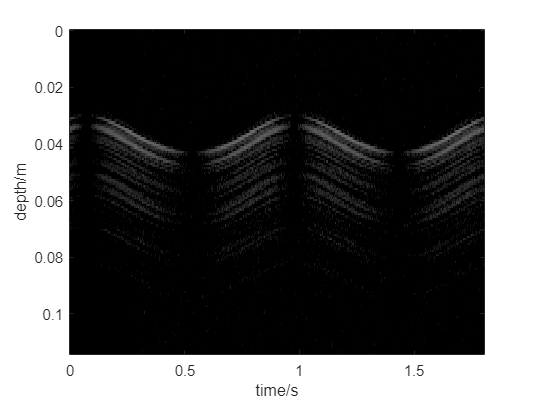

figure();
imagesc(x_axis, y_axis, 20*log10( abs( filtered_middle_beam_c) ) )
dyn_c = 40;
gain_c = -90;
caxis([-dyn_c 0]-gain_c);
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

#### Part 6

dopplerdata = load("Dopplerdata.mat");

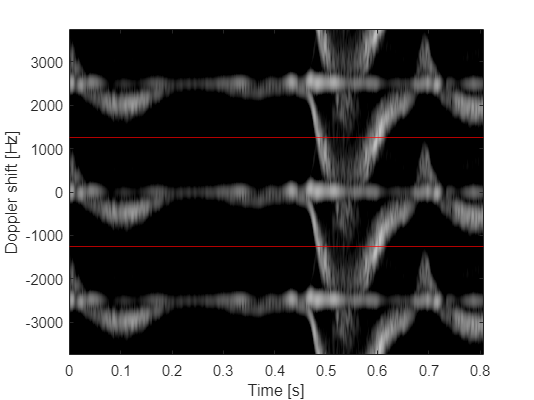

dd_iq = dopplerdata.iq;
N = 2;
%b=ones(1,N); %=boxcar(N). May also use hamming(N), hanning(N), ....
b = hamming(N);
b=b/sum(b); %Normalization of filter coefficients
iq_lp = filter(b,1,dd_iq,[],2);
iq_hp = dd_iq-iq_lp;
%since y axis is the samples and x axis is the frames
frames_dd = length(dd_iq(1,:));

Nfft_dd = 256;
crop_dd = 16;
segment = 32;
dyn_dd = 30;
gain_dd = -60;
depthindex_dd = round(size(dd_iq,1)/2)-segment:round(size(dd_iq,1)/2)+segment;
P_dd = zeros(Nfft_dd, frames_dd-crop_dd+1);
for n_dd=1:frames_dd-crop+1
    iqsegm_dd = iq_hp(depthindex_dd,n_dd+[0:crop_dd-1])';
    iqsegm_dd = iqsegm_dd.*(hamming(crop_dd)*ones(1,length(depthindex_dd)));
    P_dd(:,n_dd) = mean(abs(fftshift(fft(iqsegm_dd,Nfft_dd))).^2,2);
end
freqAxis_dd = (([0:Nfft_dd-1]/Nfft_dd)-0.5)*dopplerdata.prf;
frequencyaxis=([0:Nfft_dd-1]/Nfft_dd)-0.5;
frequencyaxis=[frequencyaxis-1, frequencyaxis, frequencyaxis+1]*dopplerdata.prf;

timeaxis_dd = (0:frames_dd-crop_dd)/dopplerdata.prf;
%nyquist limit:
max(freqAxis_dd);
lines = dopplerdata.prf/2;
P_dd_extend = [P_dd;P_dd;P_dd];
figure(), imagesc(timeaxis_dd,frequencyaxis,10*log10(P_dd_extend));
hold on;
xlabel('Time [s]'); ylabel('Doppler shift [Hz]');
set(gca,'YDir','normal')
yline(lines,'r');
yline(-lines,'r');
colormap(gray(255));
caxis([-dyn_dd 0]-gain_dd)